# Lecture 2 Matlab Data Types (Focus on Numeric Arrays)

As you might have noticed, variables in Matlab have different types, representing different forms of data (e.g. numbers, texts...). However, Matlab itself  is a l**oosely (weakly) and dynamically** typed programming language- roughly meaning that you don't have to declare a type and change types of varaibles during programming. In this lecture, we're going to briefly know the different types in Matlab, and focus on the most improtant type --numeric arrays.

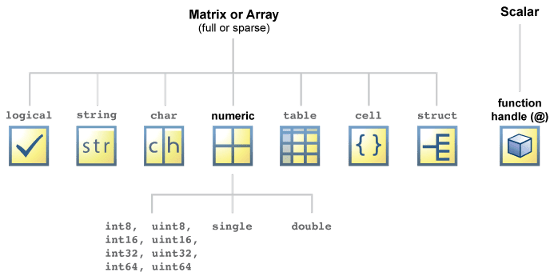

## Inspecting Matlab Data Structures with "Class" Command

class(3) % note that it is not an integer by default

ans = 'double'

class([1,2,3]) % this is the numeric array

ans = 'double'

class('matlab') % note the difference with next line 

ans = 'char'

class("hello world")

ans = 'string'

class(true)

ans = 'logical'

class(false)

ans = 'logical'

Here "double" (short for [double-precision floating-point](https://www.mathworks.com/help/matlab/matlab_prog/floating-point-numbers.html) values) is indeed the default data type for all numeric variables. Note the digits are finite in MATLAB, and therefore are indeed rational.

sin(pi)

ans = 1.2246e-16

Indeed pi is not $\pi$!

## **Matlab Numeric Arrays**

### Different array types and size

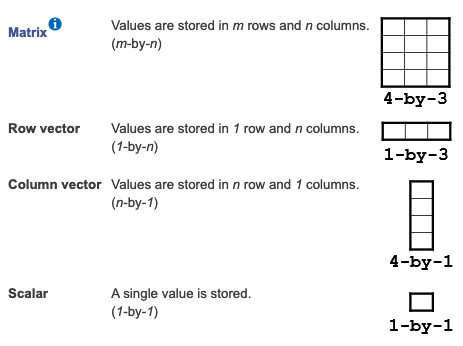

size([1,2;3,4]) %matrix

ans =      2     2


size([1,2,3,4]) %row vector 

ans =      1     4


size([1;2;3;4]) %column vector

ans =      4     1


size(1) % scalar

ans =      1     1


[1 2;3 4] % comma is not necessary

ans =      1     2
     3     4


[1 2 3 4]

ans =      1     2     3     4


[1 2 3 4]' % transpose

ans =      1
     2
     3
     4


*In-class exercise:*

create the following arrays

- column vector $\left\lbrack \begin{array}{c}
2\\
5\\
9\\
10\\
3
\end{array}\right\rbrack$

- row vector $\left\lbrack \begin{array}{cccccc}
3 & 5 & 9 & 3 & 4 & 2
\end{array}\right\rbrack$

- matrix $\left\lbrack \begin{array}{cc}
1 & 2\\
3 & 4\\
5 & 6
\end{array}\right\rbrack$

[1 2 3]

ans =      1     2     3


### Different ways to create array (in additional to manually typing)

- Evenly-spaced vector: 

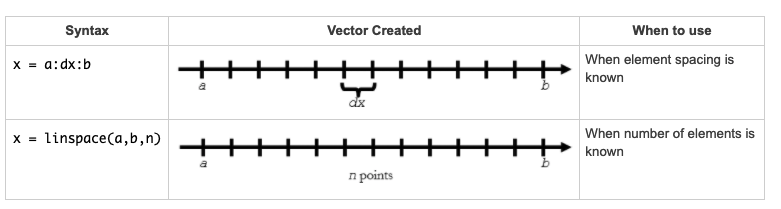

v1 = 1:1e-2:2;
size(v1)

ans =      1   101


length(v1)

ans = 101

1:5 % when step size is 1, it can be omitted

ans =      1     2     3     4     5


v2 = linspace(1,2,100);
size(v2)

ans =      1   100


v3 = 2:-1e-2:1 % negative step size

v3 =     2.0000    1.9900    1.9800    1.9700    1.9600    1.9500    1.9400    1.9300    1.9200    1.9100    1.9000    1.8900    1.8800    1.8700    1.8600    1.8500    1.8400    1.8300    1.8200    1.8100    1.8000    1.7900    1.7800    1.7700    1.7600    1.7500    1.7400    1.7300    1.7200    1.7100    1.7000    1.6900    1.6800    1.6700    1.6600    1.6500    1.6400    1.6300    1.6200    1.6100    1.6000    1.5900    1.5800    1.5700    1.5600    1.5500    1.5400    1.5300    1.5200    1.5100


v4 = linspace(2,1,100)

v4 =     2.0000    1.9899    1.9798    1.9697    1.9596    1.9495    1.9394    1.9293    1.9192    1.9091    1.8990    1.8889    1.8788    1.8687    1.8586    1.8485    1.8384    1.8283    1.8182    1.8081    1.7980    1.7879    1.7778    1.7677    1.7576    1.7475    1.7374    1.7273    1.7172    1.7071    1.6970    1.6869    1.6768    1.6667    1.6566    1.6465    1.6364    1.6263    1.6162    1.6061    1.5960    1.5859    1.5758    1.5657    1.5556    1.5455    1.5354    1.5253    1.5152    1.5051


v5 = 1:2:6.1

v5 =      1     3     5


Question: What if we want a  evenly-spaced column vector?

- Concatenation

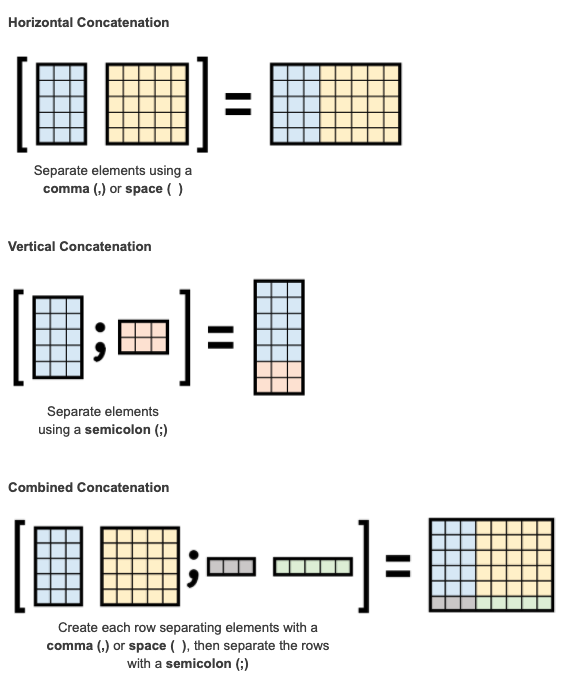

v1 = [1 2]

v1 =      1     2


v2 = [3 4]

v2 =      3     4


v3 = [v1;v2] % vertical

v3 =      1     2
     3     4


v4 = [v1 v2] %horizonal

v4 =      1     2     3     4


[v3 v4] %wrong, size does not match

Error using horzcat
Dimensions of arrays being concatenated are not consistent.

[v3;v4] %wrong, size does not match

Error using vertcat
Dimensions of arrays being concatenated are not consistent.

In-class excercise:

1.

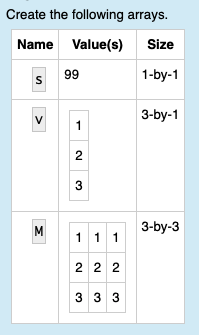

2.

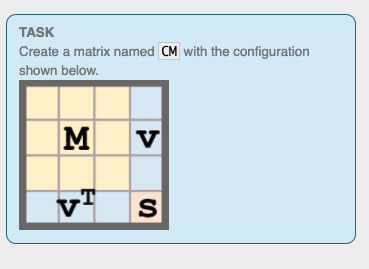

3.

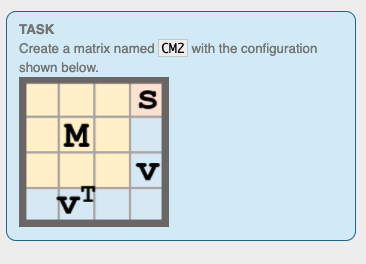

- Creation from functions

zeros(2,3) %all zero

ans =      0     0     0
     0     0     0


ones(3,1) % all one

ans =      1
     1
     1


zeros(5) %square matrix

ans =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


rand(6) % all random number with uniform distribution bewteen 0 and 1

ans =     0.8143    0.6160    0.9172    0.0759    0.5688    0.3112
    0.2435    0.4733    0.2858    0.0540    0.4694    0.5285
    0.9293    0.3517    0.7572    0.5308    0.0119    0.1656
    0.3500    0.8308    0.7537    0.7792    0.3371    0.6020
    0.1966    0.5853    0.3804    0.9340    0.1622    0.2630
    0.2511    0.5497    0.5678    0.1299    0.7943    0.6541


### Data selection and modification in numeric arrays

- Numeric Indexing

v = 2:2:20;
%single selection: put the number into ()
v(2) %second element

ans = 4

v(end) %last element

ans = 20

v(end-1)

ans = 18

% multiple selection: put the array into ()
v(1:2:end)

ans =      2     6    10    14    18


v([2,4,5])

ans =      4     8    10


modify the value

v1 = v; %make a copy of v
v1(1:2:end) = 0;
v1

v1 =      0     4     0     8     0    12     0    16     0    20


v2 = v;
v2([2,3,4]) = zeros(1,3);
v2

v2 =      2     0     0     0    10    12    14    16    18    20


For the matrix:

A = reshape(v,5,2) %change v into 5-by-2 , by default matlab is column pivot

A =      2    12
     4    14
     6    16
     8    18
    10    20


A(2,end)

ans = 14

A(2:4,2)

ans =     14
    16
    18


A(4,:) %the 4th row,  note this is different with A(4)

ans =      8    18


A(:,2) % the 2nd column, note this is different with A(2)

ans =     12
    14
    16
    18
    20


A([2,5],[1,2]) %submatrix

ans =      4    14
    10    20


A(9) % matrix is first "flattened" column-wise, then select as if it is a vector

ans = 18

B = reshape(1:9,3,3)
B ([3,1],[1,2])

**In-class Excercise:**

*Re-do the last exercise with modifying the value of a matrix (hint: initialize a matrix first)*

- Logical Indexing

v = 1:4

v =      1     2     3     4


idx = [false,false, true,true]

idx = 1×4 logical array
   0   0   1   1


v(idx)

ans =      3     4


the logical array can be created conveniently by some operators

idx = v>2

idx = 1×4 logical array
   0   0   1   1


v(idx)

ans =      3     4


v(v>2)%equivalent and faster way

ans =      3     4


R = rand(5)

R =     0.8147    0.0975    0.1576    0.1419    0.6557
    0.9058    0.2785    0.9706    0.4218    0.0357
    0.1270    0.5469    0.9572    0.9157    0.8491
    0.9134    0.9575    0.4854    0.7922    0.9340
    0.6324    0.9649    0.8003    0.9595    0.6787


R(R>.5)

ans =     0.8147
    0.9058
    0.9134
    0.6324
    0.5469
    0.9575
    0.9649
    0.9706
    0.9572
    0.8003
